# Discrete SIR Model

*Author*: Zachary del Rosario, Fall 2020

*Note:* Based on "The SIR Model for Spread of Disease", by Smith and Moore

## Implement Model

Do an initial model-development pass. A Stock and Flow diagram for this model is:

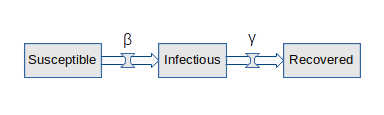

*Note:* Copied from Allen's notebook.

Use a discrete approximation to the SIR model. The deltas from timestep to timestep are:


$$\Delta I_t = - \beta I_t * S_t \\
\Delta R_t = \gamma I_t
$$


Which relate to the update rules via


$$S_{t+1} = S_t - \Delta I_t \\
I_{t+1} = I_t + \Delta I_t - \Delta R_t \\
R_{t+1} = R_t + \Delta R_t
$$


Run the model with arbitrary parmeters to test.

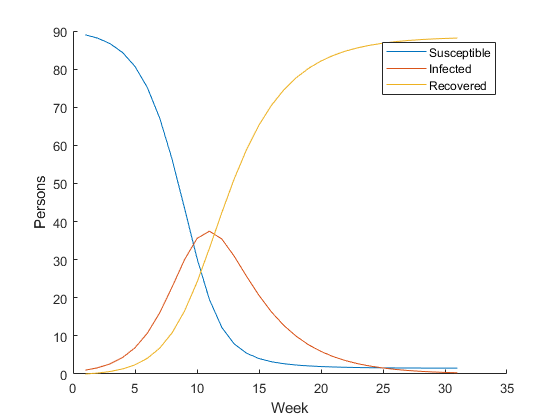

% Define parameters
tab_state = fcn_make_table( ...
    "s", 89, ...
    "i", 1, ...
    "r", 0 ...
);
tab_system = fcn_make_table("beta", 0.01, "gamma", 0.25);

% Run simulation
tab_record = fcn_simulate(tab_state, tab_system, 30);

% Plot
figure(1); clf; hold on;
plot(tab_record.s); label1 = "Susceptible";
plot(tab_record.i); label2 = "Infected";
plot(tab_record.r); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})

Summarize the results

describe(tab_record)

ans = 6×4 table
      s          i         r         stat  
    ______    _______    ______    ________

        89     37.474    88.151    "Max"   
    53.052     19.536    86.125    "Q3"    
    25.177     11.385    53.438    "Mean"  
    3.2209     5.9086    70.481    "Median"
    1.6621     1.5925    12.273    "Q1"    
    1.5317    0.31776         0    "Min"   


Students could do all of the above using the skills developed in the Bikeshare module.

## Studying data

Smith and Moore provide data on the 1968-69 Flu pandemic. Let's study those data.

% Load the data
tab_data = readtable("data.csv", "Delimiter", ",")

tab_data = 13×2 table
    week    flu_deaths
    ____    __________

      1         14    
      2         28    
      3         50    
      4         66    
      5        156    
      6        190    
      7        156    
      8        108    
      9         68    
     10         77    
     11         33    
     12         65    
     13         24    


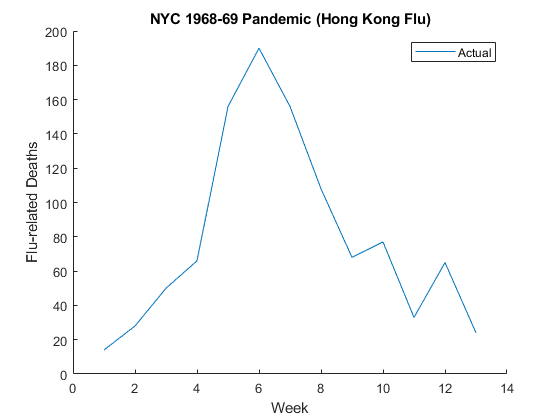


% Plot
figure(2); clf; hold on;
plot(tab_data.week, tab_data.flu_deaths); label1 = "Actual";

xlabel("Week")
ylabel("Flu-related Deaths")
legend({label1})
title("NYC 1968-69 Pandemic (Hong Kong Flu)")

Let's try to find model parameters that well-explain these data.

## Comparing Model Against Data


% Unscaled table is numerically unstable
% tab_nyc = fcn_make_table( ...
%     "s", 7900000, ...
%     "i", 10, ...
%     "r", 0 ...
% )
% Smith and Moore recommend scaling the results
nyc_pop = 7900000;
tab_nyc_scaled = fcn_make_table( ...
    "s", 1, ...
    "i", 10 / nyc_pop, ...
    "r", 0 ...
)

tab_nyc_scaled = 1×3 table
    s        i         r
    _    __________    _

    1    1.2658e-06    0


tab_flu = fcn_make_table("beta", 1/2, "gamma", 1/3)

tab_flu = 1×2 table
    beta     gamma 
    ____    _______

    0.5     0.33333


tab_nyc_record = fcn_simulate(tab_nyc_scaled, tab_flu, 140)

tab_nyc_record = 141×3 table
       s           i             r     
    _______    __________    __________

          1    1.2658e-06             0
          1    1.4768e-06    4.2194e-07
          1    1.7229e-06    9.1421e-07
          1    2.0101e-06    1.4885e-06
          1    2.3451e-06    2.1585e-06
          1    2.7359e-06    2.9402e-06
    0.99999    3.1919e-06    3.8522e-06
    0.99999    3.7239e-06    4.9162e-06
    0.99999    4.3445e-06    6.1575e-06
    0.99999    5.0686e-06    7.6057e-06
    0.99999    5.9133e-06    9.2952e-06
    0.99998    6.8988e-06    1.1266e-05
    0.99998    8.0486e-06    1.3566e-05
    0.99998    9.3899e-06    1.6249e-05
    0.99997    1.0955e-05    1.9379e-05
    0.99997     1.278e-05     2.303e-05


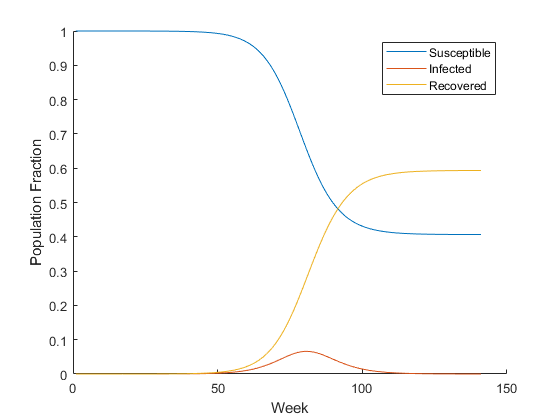


% Plot
figure(3); clf; hold on;
plot(tab_nyc_record.s); label1 = "Susceptible";
plot(tab_nyc_record.i); label2 = "Infected";
plot(tab_nyc_record.r); label3 = "Recovered";

xlabel("Week")
ylabel("Population Fraction")
legend({label1, label2, label3})

These results are scaled, we'll need to scale them back to compare against the data.

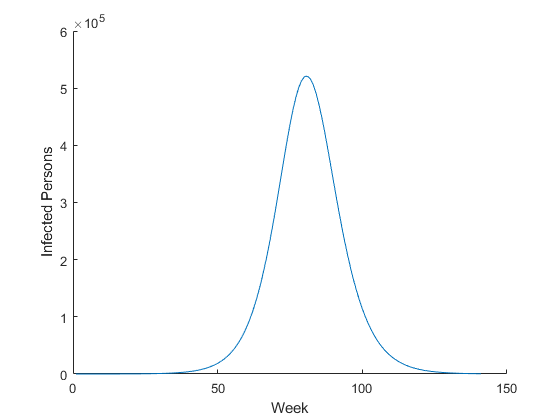

tab_nyc_flu = apply(@(x) x * nyc_pop, tab_nyc_record);

% Plot
figure(3); clf; hold on;
% plot(tab_nyc_flu.s); label1 = "Susceptible";
plot(tab_nyc_flu.i); label2 = "Infected";
% plot(tab_nyc_flu.r); label3 = "Recovered";

xlabel("Week")
ylabel("Infected Persons")

% legend({label1, label2, label3})

Compare against data; the CDC publishes data on [influenza mortality rate](https://www.cdc.gov/nchs/fastats/flu.htm).

mortality_rate = 2 / 100000; % From CDC, for a typical flu
tab_nyc_flu.d_pred = tab_nyc_flu.i * mortality_rate;
week_offset = 50;

% Plot
figure(4); clf; hold on;
plot(tab_nyc_flu.d_pred); label1 = "Predicted"

label1 = "Predicted"

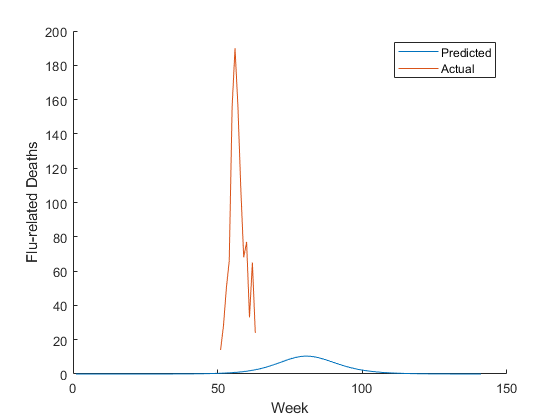

plot(tab_data.week + week_offset, tab_data.flu_deaths); label2 = "Actual";

xlabel("Week")
ylabel("Flu-related Deaths")
legend({label1, label2})

These don't line up! Need to fit parameters

## Fitting to Data

Check the "eyeball norm"

% Parameters
beta = 2.0; % Fitted by guess-and-check
% mortality_rate = 2 / 100000; % For a typical flu
mortality_rate = 4 / 100000; % 2x a typical flu
week_offset = 9; % To align model and data

tab_guess = fcn_make_table("beta", beta, "gamma", 1/3);
tab_fit_record = fcn_simulate(tab_nyc_scaled, tab_guess, 40);
tab_nyc_flu = apply(@(x) x * nyc_pop, tab_fit_record);
tab_nyc_flu.d_pred = tab_nyc_flu.i * mortality_rate;

% Plot
figure(5); clf; hold on;
plot(tab_nyc_flu.d_pred); label1 = "Predicted"

label1 = "Predicted"

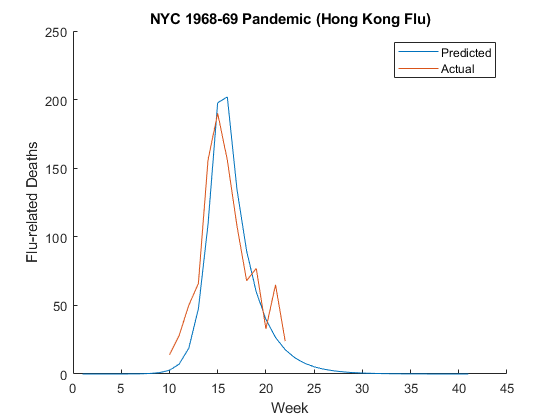

plot(tab_data.week + week_offset, tab_data.flu_deaths); label2 = "Actual";

xlabel("Week")
ylabel("Flu-related Deaths")
legend({label1, label2})
title("NYC 1968-69 Pandemic (Hong Kong Flu)")

Check a summary of the simulation.

describe(tab_nyc_flu)

ans = 6×5 table
        s             i             r          d_pred       stat  
    __________    __________    __________    ________    ________

       7.9e+06    5.0489e+06    8.2519e+06      201.96    "Max"   
    7.7178e+06    4.4972e+05    8.2416e+06      17.989    "Q3"    
    2.5922e+06     6.038e+05    4.9273e+06      24.152    "Mean"  
             0         25527    7.5873e+06      1.0211    "Median"
             0        1264.3         30587    0.050573    "Q1"    
             0            10             0      0.0004    "Min"   


We don't get any negative stocks; invariants are enforced manually in `fcn_step.m`.